# ELEC 300 Spring 2018

15.7 Nillison

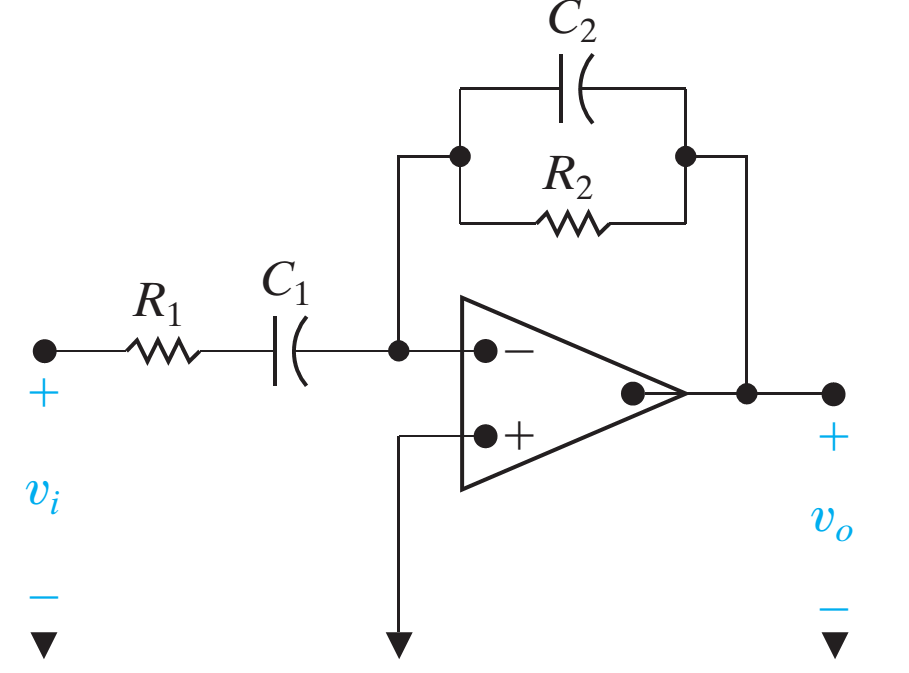

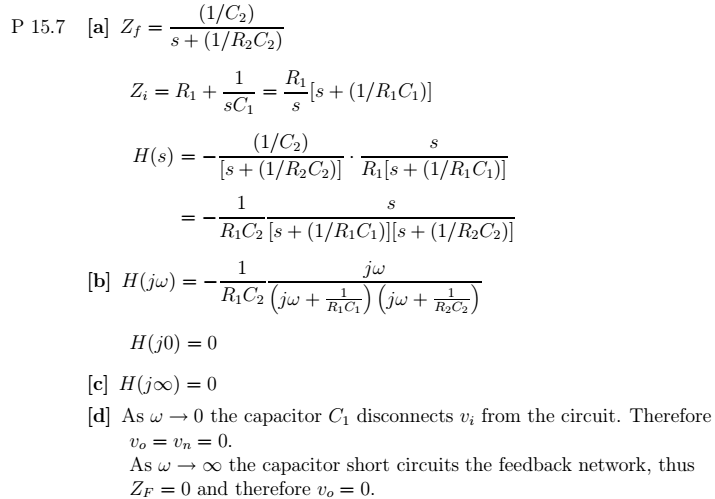

Sketch the bode plot of $H(s)=\frac{10}{s(s^2+s+16)}$

Q2H = tf([10],[1 1 16 0])


Q2H =
 
         10
  ----------------
  s^3 + s^2 + 16 s
 
Continuous-time transfer function.



BodePlotGui(Q2H)

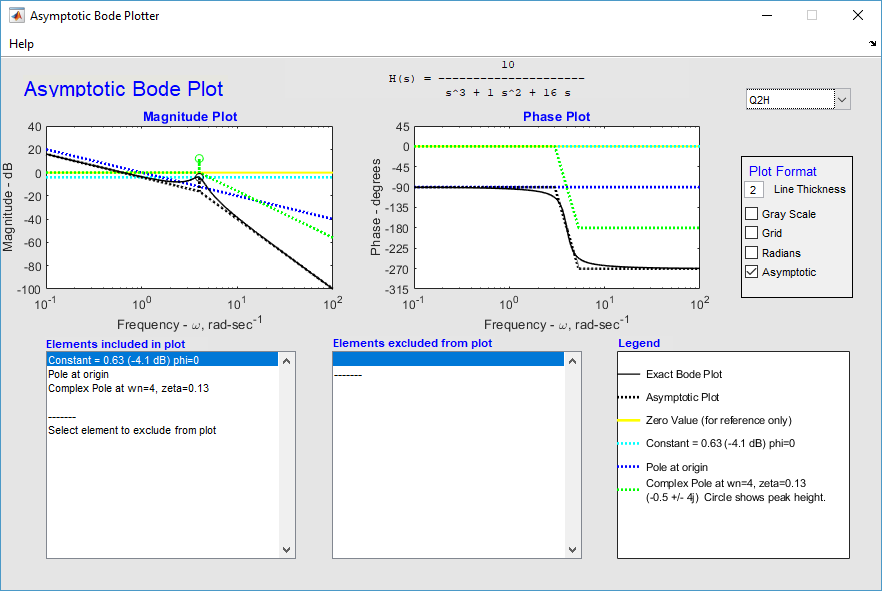

The approximation is pretty good.

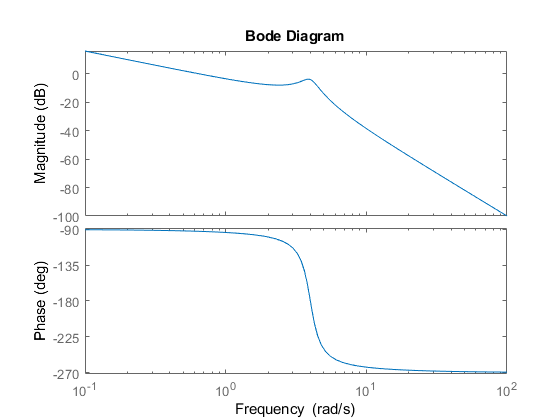

figure
bode(Q2H)

Question 3 (similar to 14.20) Nillison, taken from

**Alexander 6th edition 14.40 **A parallel resonance circuit has a resistance of

2 kΩ and half-power frequencies of 86 kHz and

90 kHz. Determine:

(a) the capacitance

(b) the inductance

(c) the resonant frequency

(d) the bandwidth

(e) the quality factor

u = symunit

u =   symbolicUnitsCollection with units:

      ampere: [1×1 sym]
      kelvin: [1×1 sym]
    kilogram: [1×1 sym]
       meter: [1×1 sym]
        mole: [1×1 sym]
      second: [1×1 sym]
     candela: [1×1 sym]

  Show all units.


fc1 = 86*u.kHz

$$fc1 = 86\,\mathrm{kHz}$$

fc2 = 90*u.kHz

$$fc2 = 90\,\mathrm{kHz}$$

R   = 2*u.kOhm

$$R = 2\,\mathrm{k\Omega}$$

% Calculations
wc1 = 2*pi*fc1

$$wc1 = 172\,\pi \,\mathrm{kHz}$$

wc2 = 2*pi*fc2

$$wc2 = 180\,\pi \,\mathrm{kHz}$$

B = wc2 - wc1

$$B = 8\,\pi \,\mathrm{kHz}$$

w0 = sqrt(wc1*wc2)

$$w0 = 12\,\pi \,\sqrt{215}\,\mathrm{kHz}$$

Q  = w0 / B

$$Q = \frac{3\,\sqrt{215}}{2}$$

C  = Q/(w0*R)

$$C = \frac{1}{16\,\pi }\,\frac{1}{\mathrm{kHz}\,\mathrm{k\Omega}}$$

Cans  = rewrite(C,u.nF)

$$Cans = \frac{125}{2\,\pi }\,\mathrm{nF}$$

L  = 1/(w0^2*C)

$$L = \frac{1}{1935\,\pi }\,\frac{\mathrm{k\Omega}}{\mathrm{kHz}}$$

Lans  = rewrite(L,u.H)

$$Lans = \frac{1}{1935\,\pi }\,H$$

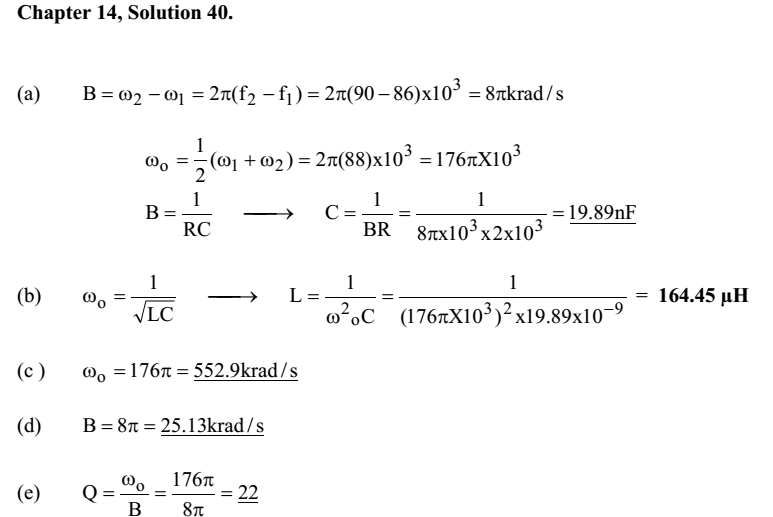

Design a first-order highpass filter using a non-inverting op amp. The transfer function is given by


$$H(s)= \frac{1+10^{-3}s}{10^{-3}s}$$


Something like the picture below, where Zf = 1/(sC), where C = 100nF, Zi = 10 k Ohm.

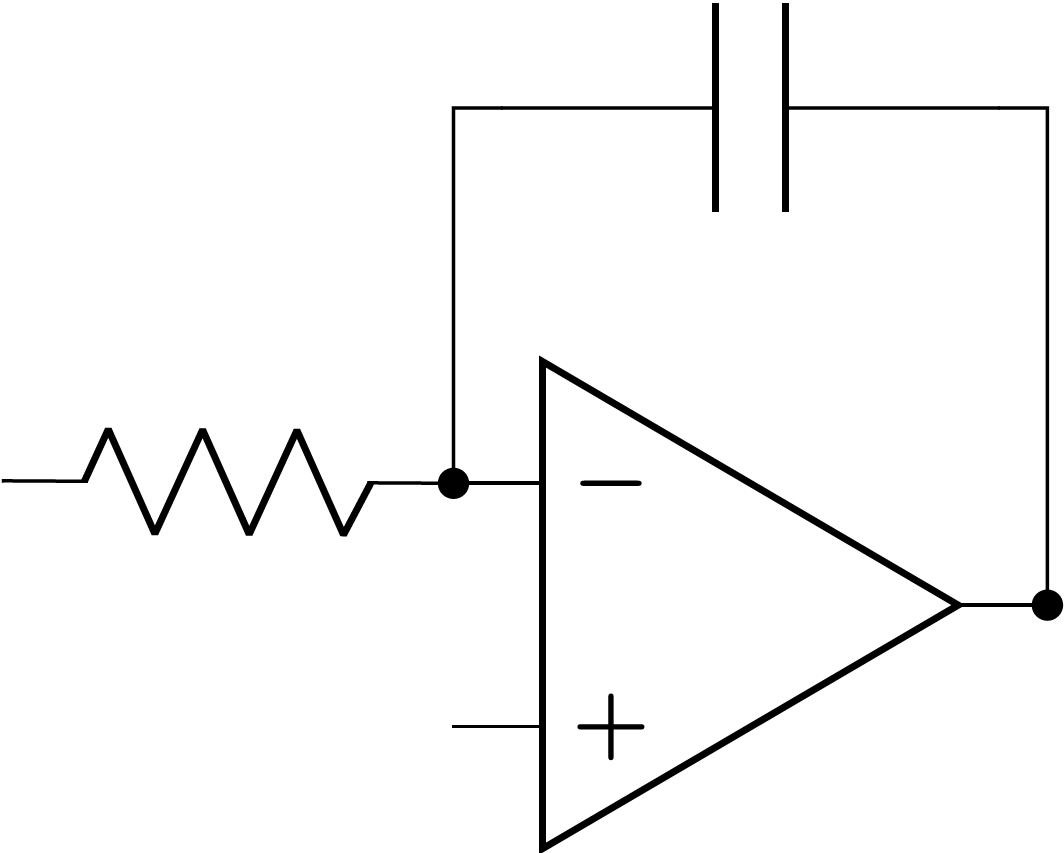

**13.45 **For the circuit shown in Fig. 13.110, find the value of the average power absorbed by the 8-Ω

resistor.

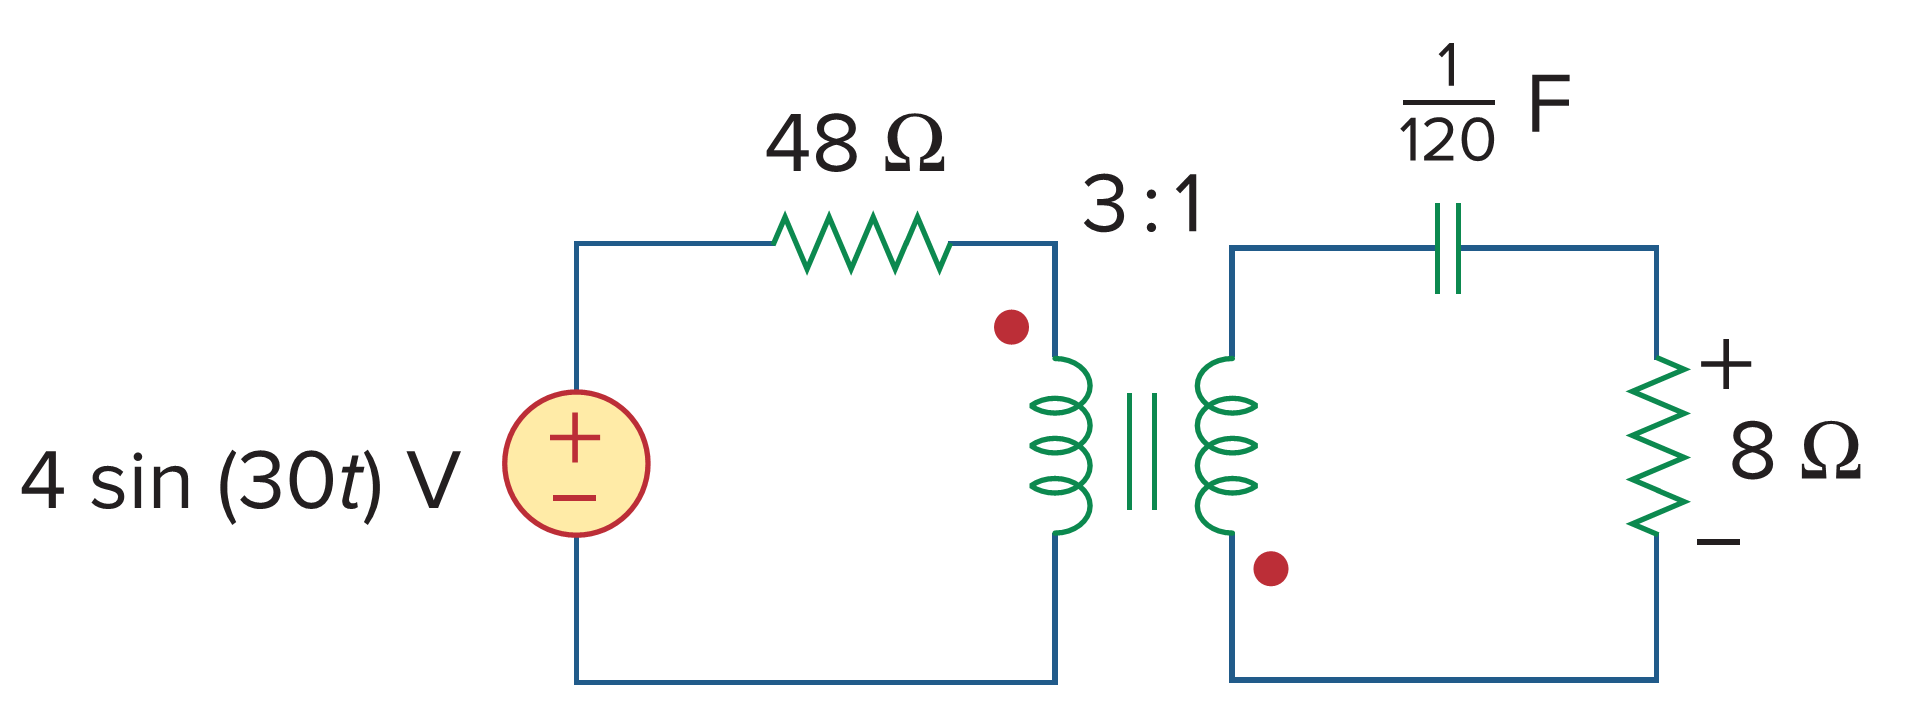

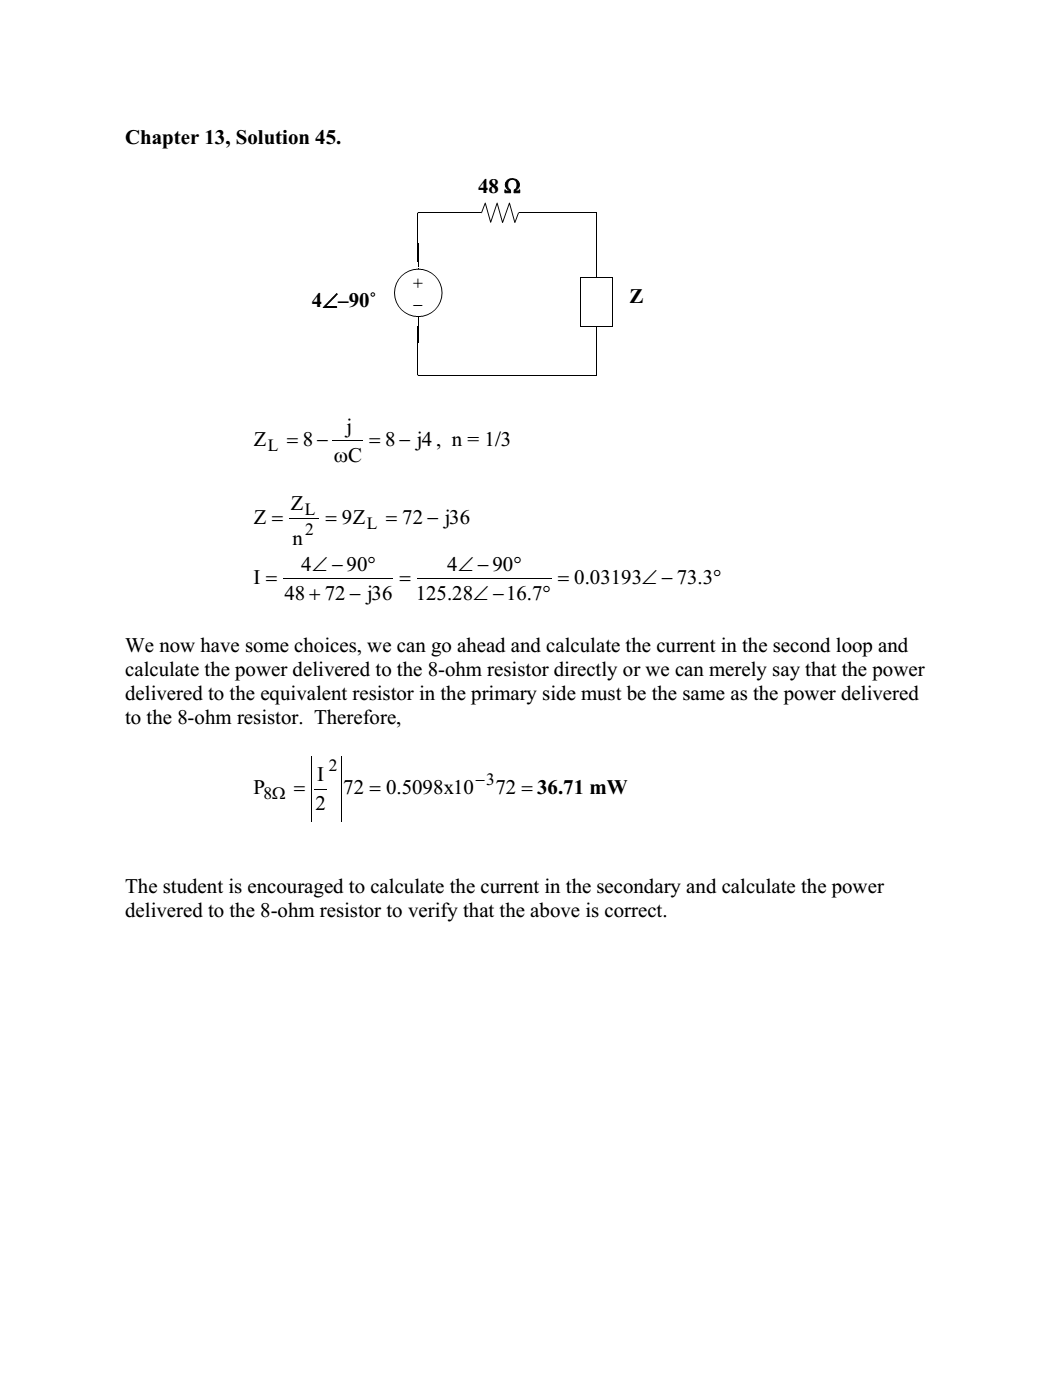

Question 6) The voltage transfer function of a system is characterized by the following pole-zero plot and a constant of K=100. What is the system's output voltage $v_o(t)$if it is excited by an input voltage of 1 u(t) V?

G6s = zpk([0],[-6-j*8 -6+j*8],100)


G6s =
 
        100 s
  -----------------
  (s^2 + 12s + 100)
 
Continuous-time zero/pole/gain model.



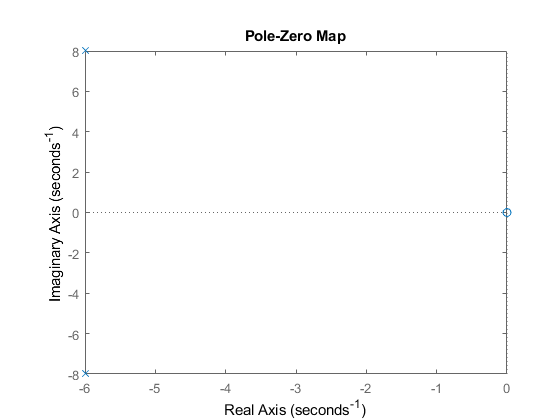

pzmap(G6s)

syms s
% Found the impulse response
timeFun = ilaplace(s/(s^2+12*s+100))

$$timeFun = {\mathrm{e}}^{-6\,t}\,\left(\cos\left(8\,t\right)-\frac{3\,\sin\left(8\,t\right)}{4}\right)$$

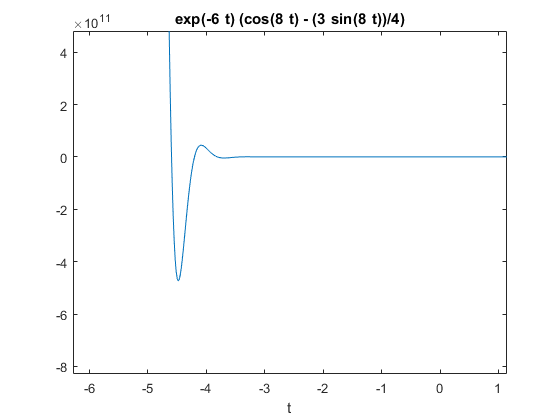

ezplot(timeFun)

% step response 
timeFun2 = ilaplace(1/(s^2+12*s+100))

$$timeFun2 = \frac{\sin\left(8\,t\right)\,{\mathrm{e}}^{-6\,t}}{8}$$

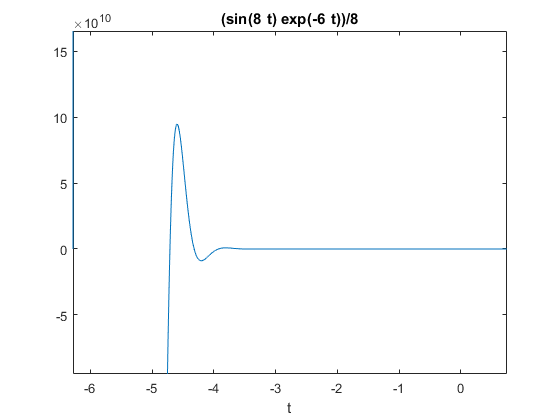

ezplot(timeFun2)

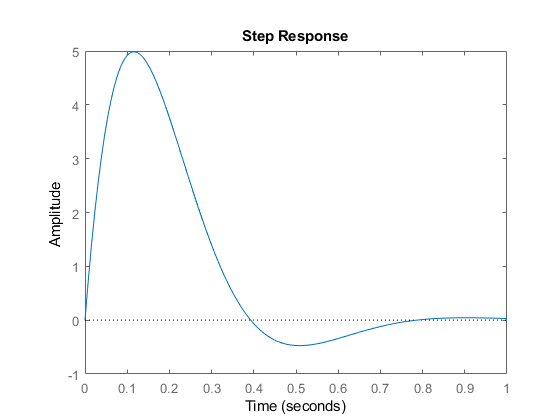

step(G6s)

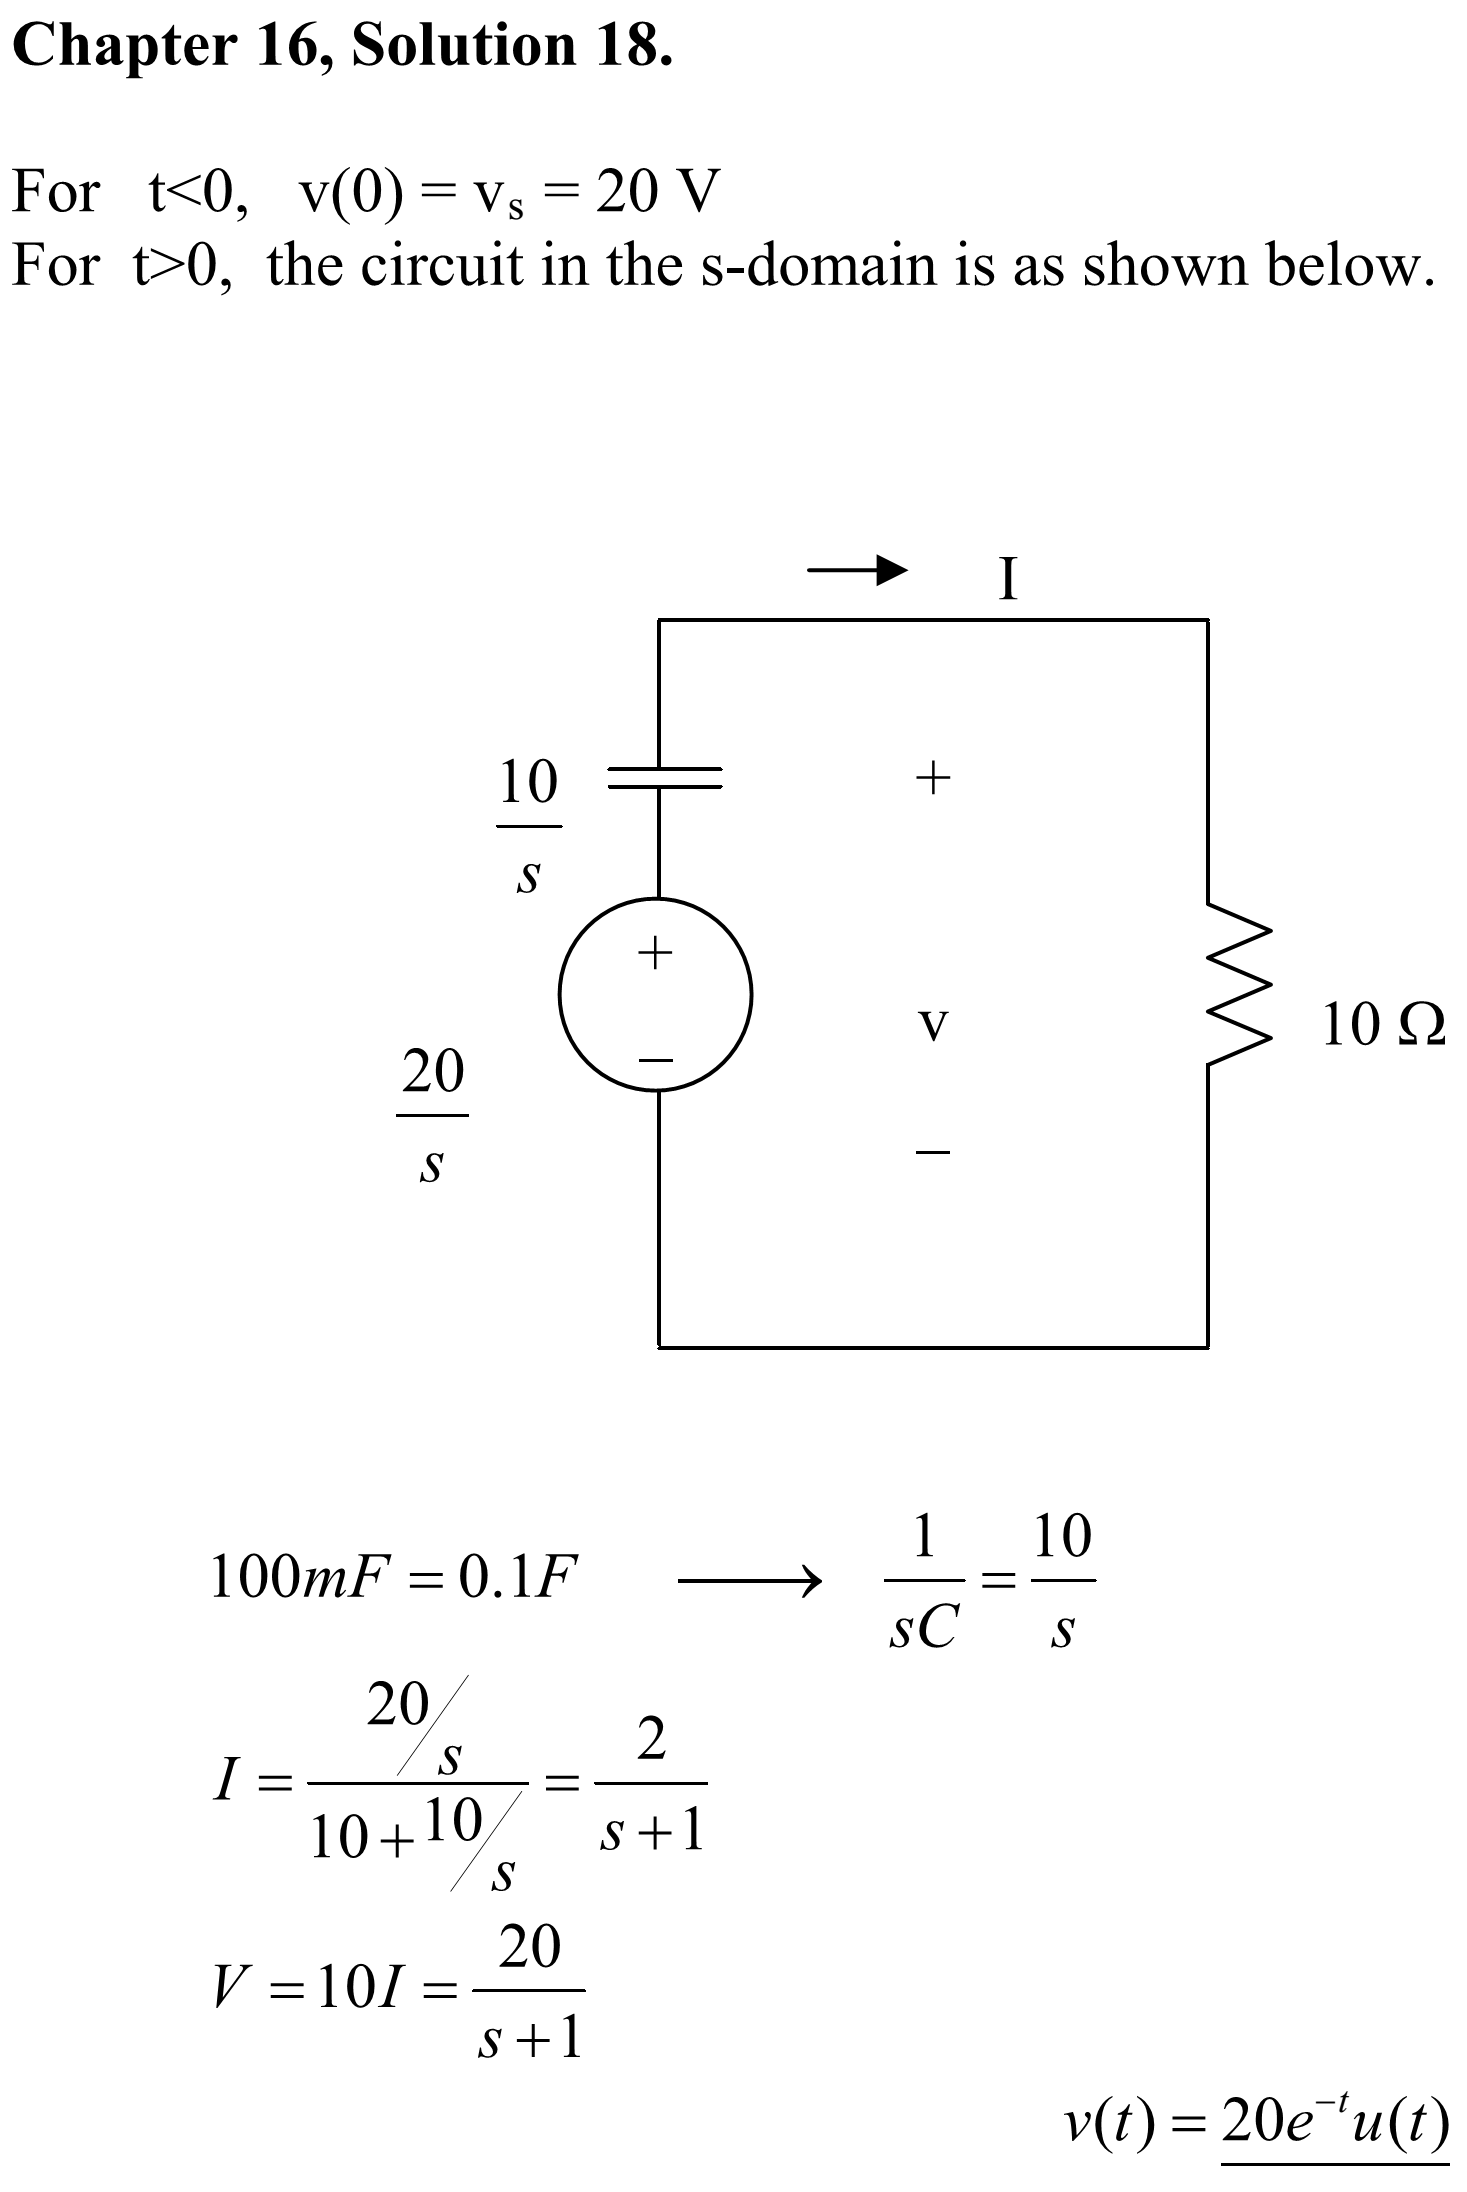

18.19 Nllison